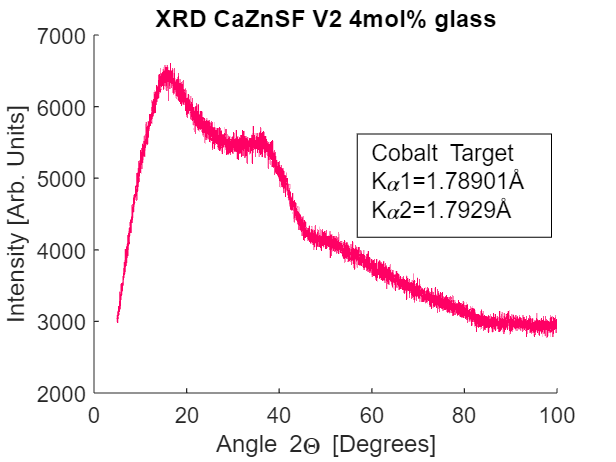

%clearing mem
clear all
clf

%importing data
% data = readtable("Year 3/Mossbauer/XRD_SLS1_raw.csv");
% tit = "SLS 1mol%";
% data = readtable("Year 3/Mossbauer/XRD_SLS4_raw.csv");
% tit = "SLS 4mol%";
% data = readtable("Year 3/Mossbauer/XRD_NBS1_raw.csv");
% tit = "NBS 1mol%";
% data = readtable("Year 3/Mossbauer/XRD_NBS4_raw.csv");
% tit = "NBS 4mol%";
% data = readtable("Year 3/Mossbauer/XRD_CaZn 1V2_raw.csv");
% tit = "CaZnSF V2 1mol%";
data = readtable("Year 3/Mossbauer/XRD_CaZn 4V2_raw.csv");
tit = "CaZnSF V2 4mol%";

%extracting data
ang = table2array(data(:,1));
int = table2array(data(:,2));

%Values (Anode material Co)
k_alpha_1 = 1.78901;
k_alpha_2 = 1.7929;

%performing plot
plot(ang,int,"Color","#FF0064")
hold on  %annotations and subsequent plots on same graph
% coeff = polyfit(ang,int,25);
% plot(ang, polyval(coeff, ang),"Color","#64FF00")

%adding annotations
dim = [.58 .1 .9 .61];

str = {
    ["Cobalt Target"],
    ["K{\alpha}1=1.78901" + char(197)],
    ["K{\alpha}2=1.7929" + char(197)]
    };

annotation('textbox',dim,'String',str,'FitBoxToText','on');

hold off %ending plotting

%labelling graph
title("XRD "+tit+" glass")
xlabel("Angle 2{\Theta} [Degrees]");
ylabel("Intensity [Arb. Units]");

%beautifying curve
ax = gca;
box off;